function images = loadMNISTImages(filename)
    fid = fopen(filename, 'rb');

    magic = fread(fid, 1, 'int32', 0, 'ieee-be');
    numImages = fread(fid, 1, 'int32', 0, 'ieee-be');
    numRows = fread(fid, 1, 'int32', 0, 'ieee-be');
    numCols = fread(fid, 1, 'int32', 0, 'ieee-be');

    images = fread(fid, inf, 'unsigned char');
    fclose(fid);

    images = reshape(images, numCols * numRows, numImages);
    images = double(images) / 255;
end

function labels = loadMNISTLabels(filename)
    fid = fopen(filename, 'rb');

    magic = fread(fid, 1, 'int32', 0, 'ieee-be');
    numLabels = fread(fid, 1, 'int32', 0, 'ieee-be');

    labels = fread(fid, inf, 'unsigned char');
    fclose(fid);

    labels = double(labels);
end

# **Standard DNN**

X_train = loadMNISTImages("path");
y_train = loadMNISTLabels("path");
X_test = loadMNISTImages("path");
y_test = loadMNISTLabels("path");

function Y = oneHotEncode(y, numClasses)
    Y = zeros(numClasses, length(y));
    for i = 1:length(y)
        Y(y(i)+1, i) = 1;
    end
end

Y_train = oneHotEncode(y_train, 10);
Y_test  = oneHotEncode(y_test, 10);

rng(1);
W1 = 0.01 * randn(128, 784);
b1 = zeros(128, 1);
W2 = 0.01 * randn(64, 128);
b2 = zeros(64, 1);
W3 = 0.01 * randn(10, 64);
b3 = zeros(10, 1);

epochs = 100;
batch_size = 128;
lr = 0.01;
num_samples = size(X_train, 2);
num_batches = floor(num_samples / batch_size);
loss_history = zeros(epochs, 1);

for epoch = 1:epochs
    perm = randperm(num_samples);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:, idx);
        Y = Y_train(:, idx);
        m = size(X,2);
        Z1 = W1*X + b1;
        A1 = max(0, Z1);
        Z2 = W2*A1 + b2;
        A2 = max(0, Z2);
        Z3 = W3*A2 + b3;
        Z3 = Z3 - max(Z3, [], 1);
        expZ = exp(Z3);
        Y_hat = expZ ./ sum(expZ,1);
        loss = -sum(sum(Y .* log(Y_hat))) / m;
        epoch_loss = epoch_loss + loss;
        dZ3 = Y_hat - Y;
        dW3 = (1/m) * dZ3 * A2';
        db3 = (1/m) * sum(dZ3,2);
        dA2 = W3' * dZ3;
        dZ2 = dA2 .* (Z2 > 0);
        dW2 = (1/m) * dZ2 * A1';
        db2 = (1/m) * sum(dZ2,2);
        dA1 = W2' * dZ2;
        dZ1 = dA1 .* (Z1 > 0);
        dW1 = (1/m) * dZ1 * X';
        db1 = (1/m) * sum(dZ1,2);
        W3 = W3 - lr*dW3;  b3 = b3 - lr*db3;
        W2 = W2 - lr*dW2;  b2 = b2 - lr*db2;
        W1 = W1 - lr*dW1;  b1 = b1 - lr*db1;
    end
    loss_history(epoch) = epoch_loss / num_batches;
    fprintf('Epoch %d/%d | Loss: %.4f\n', epoch, epochs, loss_history(epoch));
end

Epoch 1/100 | Loss: 2.3020
Epoch 2/100 | Loss: 2.3012
Epoch 3/100 | Loss: 2.3005
Epoch 4/100 | Loss: 2.2996
Epoch 5/100 | Loss: 2.2978
Epoch 6/100 | Loss: 2.2916
Epoch 7/100 | Loss: 2.2479
Epoch 8/100 | Loss: 1.9705
Epoch 9/100 | Loss: 1.4551
Epoch 10/100 | Loss: 1.0161
Epoch 11/100 | Loss: 0.7701
Epoch 12/100 | Loss: 0.6658
Epoch 13/100 | Loss: 0.6158
Epoch 14/100 | Loss: 0.5824
Epoch 15/100 | Loss: 0.5543
Epoch 16/100 | Loss: 0.5290
Epoch 17/100 | Loss: 0.5032
Epoch 18/100 | Loss: 0.4741
Epoch 19/100 | Loss: 0.4444
Epoch 20/100 | Loss: 0.4185
Epoch 21/100 | Loss: 0.3973
Epoch 22/100 | Loss: 0.3799
Epoch 23/100 | Loss: 0.3645
Epoch 24/100 | Loss: 0.3511
Epoch 25/100 | Loss: 0.3384
Epoch 26/100 | Loss: 0.3270
Epoch 27/100 | Loss: 0.3154
Epoch 28/100 | Loss: 0.3049
Epoch 29/100 | Loss: 0.2950
Epoch 30/100 | Loss: 0.2856
Epoch 31/100 | Loss: 0.2764
Epoch 32/100 | Loss: 0.2670
Epoch 33/100 | Loss: 0.2585
Epoch 34/100 | Loss: 0.2503
Epoch 35/100 | Loss: 0.2429
Epoch 36/100 | Loss: 0.2353
E

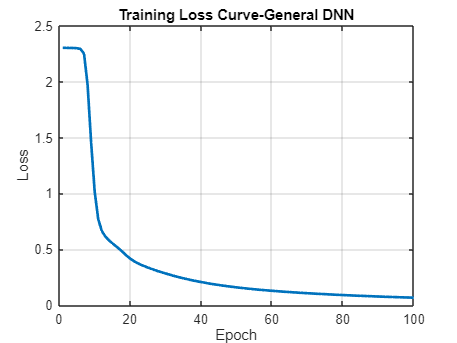

figure;
plot(loss_history, 'LineWidth', 2);
xlabel('Epoch');
ylabel('Loss');
title('Training Loss Curve-General DNN');
grid on;

Z1 = W1*X_test + b1;
A1 = max(0, Z1);
Z2 = W2*A1 + b2;
A2 = max(0, Z2);
Z3 = W3*A2 + b3;
[~, predictions] = max(Z3, [], 1);
predictions = predictions - 1;

accuracy = mean(predictions' == y_test) * 100;
fprintf('Test Accuracy for general DNN: %.2f%%\n', accuracy);

Test Accuracy for general DNN: 97.10%


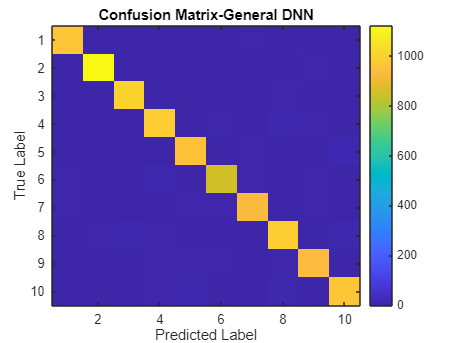

conf_mat = zeros(10,10);
for i = 1:length(y_test)
    true_label = y_test(i) + 1;
    pred_label = predictions(i) + 1;
    conf_mat(true_label, pred_label) = conf_mat(true_label, pred_label) + 1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted Label');
ylabel('True Label');
title('Confusion Matrix-General DNN');

# **SVD modified DNN **

d0 = 784; d1 = 128; d2 = 64; d3 = 10;
r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);
rng(1);
[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0);
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0);
[V3,~] = qr(randn(d2,r3),0);
alpha3 = randn(r3,1);

epochs = 100;
batch_size = 128;
lr = 1e-3;
lambda_orth = 1e-3;
lambda_sparse = 1e-3;
N = size(X_train,2);
num_batches = floor(N/batch_size);
loss_hist = zeros(epochs,1);

for epoch = 1:epochs
    perm = randperm(N);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);
        s1 = exp(alpha1);  S1 = diag(sqrt(s1));
        s2 = exp(alpha2);  S2 = diag(sqrt(s2));
        s3 = exp(alpha3);  S3 = diag(sqrt(s3));
        H1 = S1*(V1'*X);        Z1 = U1*S1*H1;  A1 = max(0,Z1);
        H2 = S2*(V2'*A1);       Z2 = U2*S2*H2;  A2 = max(0,Z2);
        H3 = S3*(V3'*A2);       Z3 = U3*S3*H3;
        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3) ./ sum(exp(Z3),1);
        CE = -sum(sum(Y .* log(Yhat))) / m;
        Orth = ...
            norm(U1'*U1-eye(size(U1,2)),'fro')^2 + norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
            norm(U2'*U2-eye(size(U2,2)),'fro')^2 + norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
            norm(U3'*U3-eye(size(U3,2)),'fro')^2 + norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        Sparse = norm(s1,1)/norm(s1,2) + norm(s2,1)/norm(s2,2) + norm(s3,1)/norm(s3,2);
        loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        epoch_loss = epoch_loss + loss;
        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;
        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));
        ds3 = ds3 + lambda_sparse*( sign(s3)/norm(s3,2) - (norm(s3,1)/(norm(s3,2)^3))*s3 );
        dA2 = V3*(S3*dH3);     dZ2 = dA2 .* (Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;
        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));
        ds2 = ds2 + lambda_sparse*( sign(s2)/norm(s2,2) - (norm(s2,1)/(norm(s2,2)^3))*s2 );
        dA1 = V2*(S2*dH2);     dZ1 = dA1 .* (Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;
        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));
        ds1 = ds1 + lambda_sparse*( sign(s1)/norm(s1,2) - (norm(s1,1)/(norm(s1,2)^3))*s1 );
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);
        U1 = U1 - lr*dU1;  V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2;  V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3;  V3 = V3 - lr*dV3;
    end
    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf('Epoch %d | Loss %.4f\n', epoch, loss_hist(epoch));
end

Epoch 1 | Loss 1.3523
Epoch 2 | Loss 0.7509
Epoch 3 | Loss 0.5675
Epoch 4 | Loss 0.4765
Epoch 5 | Loss 0.4260
Epoch 6 | Loss 0.3929
Epoch 7 | Loss 0.3687
Epoch 8 | Loss 0.3500
Epoch 9 | Loss 0.3337
Epoch 10 | Loss 0.3202
Epoch 11 | Loss 0.3085
Epoch 12 | Loss 0.2991
Epoch 13 | Loss 0.2892
Epoch 14 | Loss 0.2812
Epoch 15 | Loss 0.2732
Epoch 16 | Loss 0.2667
Epoch 17 | Loss 0.2600
Epoch 18 | Loss 0.2537
Epoch 19 | Loss 0.2476
Epoch 20 | Loss 0.2425
Epoch 21 | Loss 0.2371
Epoch 22 | Loss 0.2326
Epoch 23 | Loss 0.2276
Epoch 24 | Loss 0.2229
Epoch 25 | Loss 0.2188
Epoch 26 | Loss 0.2151
Epoch 27 | Loss 0.2114
Epoch 28 | Loss 0.2076
Epoch 29 | Loss 0.2041
Epoch 30 | Loss 0.2007
Epoch 31 | Loss 0.1976
Epoch 32 | Loss 0.1944
Epoch 33 | Loss 0.1917
Epoch 34 | Loss 0.1891
Epoch 35 | Loss 0.1860
Epoch 36 | Loss 0.1834
Epoch 37 | Loss 0.1814
Epoch 38 | Loss 0.1786
Epoch 39 | Loss 0.1759
Epoch 40 | Loss 0.1743
Epoch 41 | Loss 0.1715
Epoch 42 | Loss 0.1696
Epoch 43 | Loss 0.1672
Epoch 44 | Loss 0.16

energy_thresh = 0.99;
prune = @(s) find(cumsum(sort(s.^2,'descend'))/sum(s.^2) >= energy_thresh,1);
r1p = prune(exp(alpha1));
r2p = prune(exp(alpha2));
r3p = prune(exp(alpha3));
[~,i1] = sort(exp(alpha1),'descend');
[~,i2] = sort(exp(alpha2),'descend');
[~,i3] = sort(exp(alpha3),'descend');
U1 = U1(:,i1(1:r1p));  V1 = V1(:,i1(1:r1p));  alpha1 = alpha1(i1(1:r1p));
U2 = U2(:,i2(1:r2p));  V2 = V2(:,i2(1:r2p));  alpha2 = alpha2(i2(1:r2p));
U3 = U3(:,i3(1:r3p));  V3 = V3(:,i3(1:r3p));  alpha3 = alpha3(i3(1:r3p));

S1 = diag(sqrt(exp(alpha1)));
S2 = diag(sqrt(exp(alpha2)));
S3 = diag(sqrt(exp(alpha3)));
H1 = S1*(V1'*X_test);  A1 = max(0,U1*S1*H1);
H2 = S2*(V2'*A1);      A2 = max(0,U2*S2*H2);
H3 = S3*(V3'*A2);      Z3 = U3*S3*H3;
[~,pred] = max(Z3,[],1);
pred = pred - 1;
acc = mean(pred'==y_test)*100;
fprintf('Final Accuracy: %.2f%%\n', acc);

Final Accuracy: 94.86%


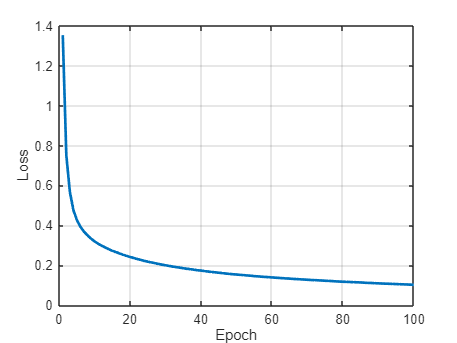

figure;
plot(loss_hist,'LineWidth',2);
xlabel('Epoch'); ylabel('Loss'); grid on;

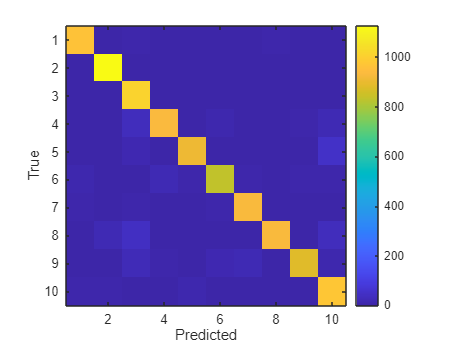

conf_mat = zeros(10,10);
for i=1:length(y_test)
    conf_mat(y_test(i)+1,pred(i)+1) = conf_mat(y_test(i)+1,pred(i)+1)+1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted'); ylabel('True');
axis square;